# The Cahn-Hilliard equation for living tissue.

## Introduction

The Cahn-Hilliard equation for living tissue is a variant of the well-known Cahn-Hilliard model. This variant contains several changes compared to the original equation to give a phenomenological representation of how cells interact. Hence, this variant is called the *degenerate Cahn-Hilliard model with singular single-well potential *and reads 


$$\begin{cases}
\partial_t n = \nabla\cdot\left(n(1-n)^\alpha\nabla\mu \right),\\
\mu = -\gamma \Delta n + \psi^\prime(n).
\end{cases}$$


In this model:

- $n$ is the order parameter, *i.e.* a relative quantity such as a cell density or a a volume fraction $n = \frac{n_1}{n_1+n_2}.$

- $\mu$ is the chemical potential and contaains the effects of both surface tension $-\gamma \Delta n$ and the attractive/repulsive forces $\psi^\prime(n)$.

The potential is assumed to be a single-well logarithmic function such as 


$$\psi(n) = -(1-n^\star)\log(1-n) - n^3/3 - (1-n^\star)n^2/2-(1-n^\star)n+k.$$


Solutions of this model are expected to remain in the bounds $0\le n<1$. To obtain this result numerically we adapt the work of [Bubba and Poulain (2020)](https://arxiv.org/abs/1910.13211) in the finite volume framework.

## The code

close all; clear all; format long;

### Model parameters

gamma = 1e-4; % squared of length of diffuse interface
alpha=2; % exponent for mobility
nstar = 0.6; % equilibrium density for attraction/repulsion
k = 10; % constant to have a positive energy

b = @(n) n.*(1-n).^alpha; % mobility function
psip = @(n) (1-nstar)./(1-n) - n.^2 - (1-nstar).*n -(1-nstar); % derivative of potential
psi = @(n) -(1-nstar).*log(1-n) - n.^3./3 - (1-nstar).*n.^2./2 -(1-nstar).*n +k;

### Time and space discretization

% time discretization
T = 2;   % end time
dt = 1e-6; % time step
t = 0:dt:T; % grid
CFL=0.0001; % constant for CFL condition

% space discretization
nbx = 100;   % Number of points in the domain
L = 1;   % length of domain
xm=0;   % start of domain
xM=1;   % end of the domain
h = (xM-xm)/(nbx-1);   % grid space
x = xm:h:xM;   % discretization

### Initial conditions

r = -1 + (2)*rand(nbx,1);
n = abs(0.3+0.05*r);  % Random numbers
mu = zeros(nbx,1);
mu(2:nbx-1) = -gamma *(n(3:nbx)-2*n(2:nbx-1)+n(1:nbx-2))./h.^2 + psip(n(2:nbx-1));
mu(1) = -gamma*(n(2)-n(1))./h^2 + psip(n(1));
mu(nbx) = -gamma*(-n(nbx)+n(nbx-1))./h^2 + psip(n(nbx));

% initialisation flux at boundary of cells
fluxm_h = zeros(nbx+1,1); 

### Temporal loop

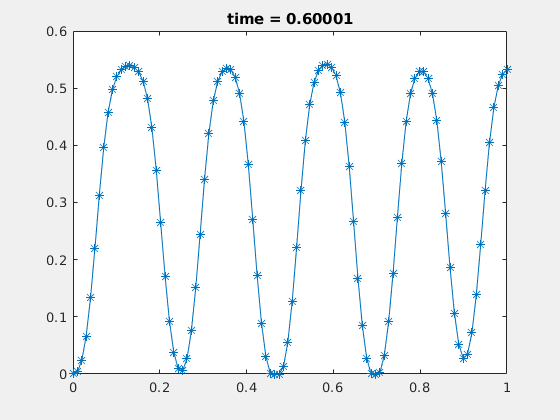

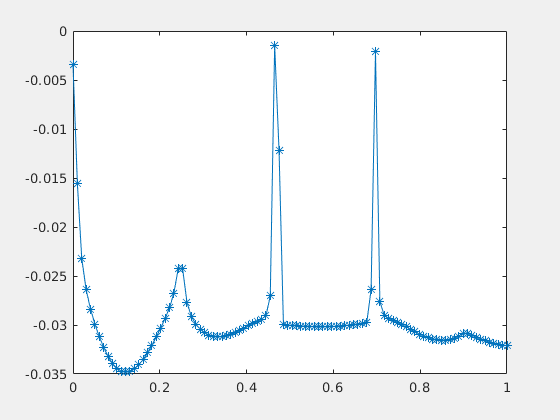

tt = dt; inc = 1; inc2=1; tt_plot=0;
%%
while(tt < T)
    tt;
    % the velocity here is minus the gradient of mu
    v=zeros(nbx+1,1);
    v(2:nbx) = -(mu(2:nbx)-mu(1:nbx-1))./h;
    
    % compute flux: the upwind method is applied as in Poulain and Bubba
    % (2020) (see the code of the function for details)
    fluxm_h = upwind_flux_degenerate_mobility(n,v,nbx,h,dt,alpha);
    
    % CFL condition: adaptive time step
    dt = 1e-5; 
    dt = min(dt, CFL.*h./max(abs(v)));
    % compute solution
    % density
    n = n - dt*(fluxm_h(2:nbx+1)-fluxm_h(1:nbx))./h;
    % chemical potential
    mu(2:nbx-1) = -gamma* (n(3:nbx)-2*n(2:nbx-1)+n(1:nbx-2))./(h.^2) + psip(n(2:nbx-1));
    mu(1) = -gamma*(n(2)-n(1))./(h^2) + psip(n(1));
    mu(nbx) = -gamma*(-n(nbx)+n(nbx-1))./(h^2) + psip(n(nbx));
    
    % plot the solution during simulation 
    if tt_plot>0.1
        tt_plot=0;
        figure(1)
        plot(x,n, '-*')
        set(gcf,'Visible','on')
        title("time = " + tt)
        figure(2)
        plot(x,mu, '-*')
        set(gcf,'Visible','on')
        mass(inc2) = h*sum(n);
        figure(3)
        plot(mass)
        inc2=inc2+1;
    end
    inc = inc +1;
    tt = tt+dt;
    tt_plot=tt_plot+dt;
end